close all
clear all

pkm = PKModelDesign;
pkc1 = addCompartment(pkm, 'Central', ...
                     'DosingType', 'Bolus', ...
                     'EliminationType', 'linear-clearance', ...
                     'HasResponseVariable', true);
pkc2 = addCompartment(pkm, 'Peripheral', 'HasResponseVariable', true);

Construct and configure the model.

model = construct(pkm);
configset = getconfigset(model);
configset.CompileOptions.UnitConversion = true;

## Check Model

(Note: default values. These will be changed in next two sections.)

View the components that were automatically created with this model at default parameters.  Reactions are automatically set with mass action kinetic laws (first-order kinetics).  Running this section will allow you to see array headers to use `sbioselect()` and re-define any specific values.

model.Compartments % confirms compartments in the model

ans =    SimBiology Compartment Array

   Index:    Name:         Value:    Units:
   1         Central       1         liter 
   2         Peripheral    1         liter 


model.Reactions % all reactions in the two-compartment model

ans =    SimBiology Reaction Array

   Index:    Reaction:                                               
   1         Central.Dose_Central -> Central.Drug_Central            
   2         Central.Drug_Central -> null                            
   3         Peripheral.Dose_Peripheral -> Peripheral.Drug_Peripheral
   4         Central.Drug_Central <-> Peripheral.Drug_Peripheral     


model.Parameters % all default, pre-defined rate constants

ans =    SimBiology Parameter Array

   Index:    Name:              Value:    Units:    
   1         ka_Central         0         1/hour    
   2         Tk0_Central        1         hour      
   3         TLag_Central       1         hour      
   4         Cl_Central         1         liter/hour
   5         ke_Central         1         1/hour    
   6         ka_Peripheral      0         1/hour    
   7         Tk0_Peripheral     1         hour      
   8         TLag_Peripheral    1         hour      
   9         Q12                1         liter/hour
   10        k12                1         1/hour    
   11        k21                1         1/hour    


model.Rules % all rate initialization equations

ans =    SimBiology Rule Array

   Index:    RuleType:            Rule:                            
   1         initialAssignment    ke_Central = Cl_Central / Central
   2         initialAssignment    k12 = Q12 / Central              
   3         initialAssignment    k21 = Q12 / Peripheral           


model.Species % dose and drug representations

ans =    SimBiology Species Array

   Index:    Compartment:    Name:              Value:    Units:         
   1         Central         Dose_Central       0         milligram      
   2         Central         Drug_Central       0         milligram/liter
   3         Peripheral      Dose_Peripheral    0         milligram      
   4         Peripheral      Drug_Peripheral    0         milligram/liter


## Redefine Compartment Capacities.

5 L/kg * 0.35 kg rat = 1.75 L (Kyerematen)

vc = sbioselect(model,'Name','Central'); % selects Central compartment
set(vc,'Capacity',1.75)

Confirm updates to the model (Note: for specific checks, `get()` can be used for variables assigned with `sbioselect()` (e.g., `ke = sbioselect(model,'Name','ke_Central'); get(ke)`)

model.Compartments

ans =    SimBiology Compartment Array

   Index:    Name:         Value:    Units:
   1         Central       1.75      liter 
   2         Peripheral    1         liter 


## Redefine desired values for any pre-defined rate parameters.

**Elimination Rate Constant **(using beta rate here = slower (final) rate of elimination):

Kel = CL/Vd

t1/2 = 0.693/Kel

selected 52 min for t1/2 based on Kyerematen, which requires kel = 0.8

kelim = sbioselect(model,'Name','ke_Central'); % selects ke_Central parameter
set(kelim,'Value',0.8); % this will update the parameter value inside the model directly

% get(ke) % to check specific parameter

**Clearance Rate Constant** (from central compartment):

CL = Ke * Vd (from Ke = CL/Vd), so CL = (0.8)*(1.75) = 1.4

**Forward & Reverse Rate Constants:**

from Shivange et al 2019 (Lester lab, Caltech)

CL = sbioselect(model,'Name','Cl_Central');
set(CL,'Value',1.4);
forward = sbioselect(model,'Name','k12');
set(forward,'Value',1.5); % Shivange 1.5
reverse = sbioselect(model,'Name','k21');
set(reverse,'Value',1.2); % Shivange 1.2

Confirm updates to the model (Note: for specific checks, `get()` can be used for variables assigned with `sbioselect()` (e.g., `ke = sbioselect(model,'Name','ke_Central'); get(ke)`)

model.Parameters

ans =    SimBiology Parameter Array

   Index:    Name:              Value:    Units:    
   1         ka_Central         0         1/hour    
   2         Tk0_Central        1         hour      
   3         TLag_Central       1         hour      
   4         Cl_Central         1.4       liter/hour
   5         ke_Central         0.8       1/hour    
   6         ka_Peripheral      0         1/hour    
   7         Tk0_Peripheral     1         hour      
   8         TLag_Peripheral    1         hour      
   9         Q12                1         liter/hour
   10        k12                1.5       1/hour    
   11        k21                1.2       1/hour    


## Drug Administration

d2 = sbiodose('d2', 'schedule');

load ivsatrials

for i = 1:length(ivsatrials)
inftimes = ivsatrials(i).infusiontimes';
d2.Time = inftimes/3600; 

d2.TimeUnits = 'hour';
d2.Amount = zeros(1,numel(d2.Time));
d2.Amount(:,:) = 0.01; % 0.01 mg for 0.03 mg/kg infusion in a 350 g rat
d2.AmountUnits = 'milligram';
d2.TargetName = 'Drug_Central'; 

## Simulate the Model

Change the simulation stop time to 24 hours.

cs = getconfigset(model);
cs.StopTime = 24;
cs.TimeUnits = 'hour';

In addition, do not log the dose species data as you are mainly interested in monitoring the drug species which is the drug concentration in the system. This makes visualizing the species in a plot more convenient. To accomplish this, set the `StatesToLog` property to include the species `drug` only.

cs.RuntimeOptions.StatesToLog = {'Drug_Central','Drug_Peripheral'};

Simulate the model using the dosing schedule defined by the d2 dose object.

[t,sd,species] = sbiosimulate(model,d2);

## Plot Results

Plot the concentration versus the time profile of the drug in the compartment.

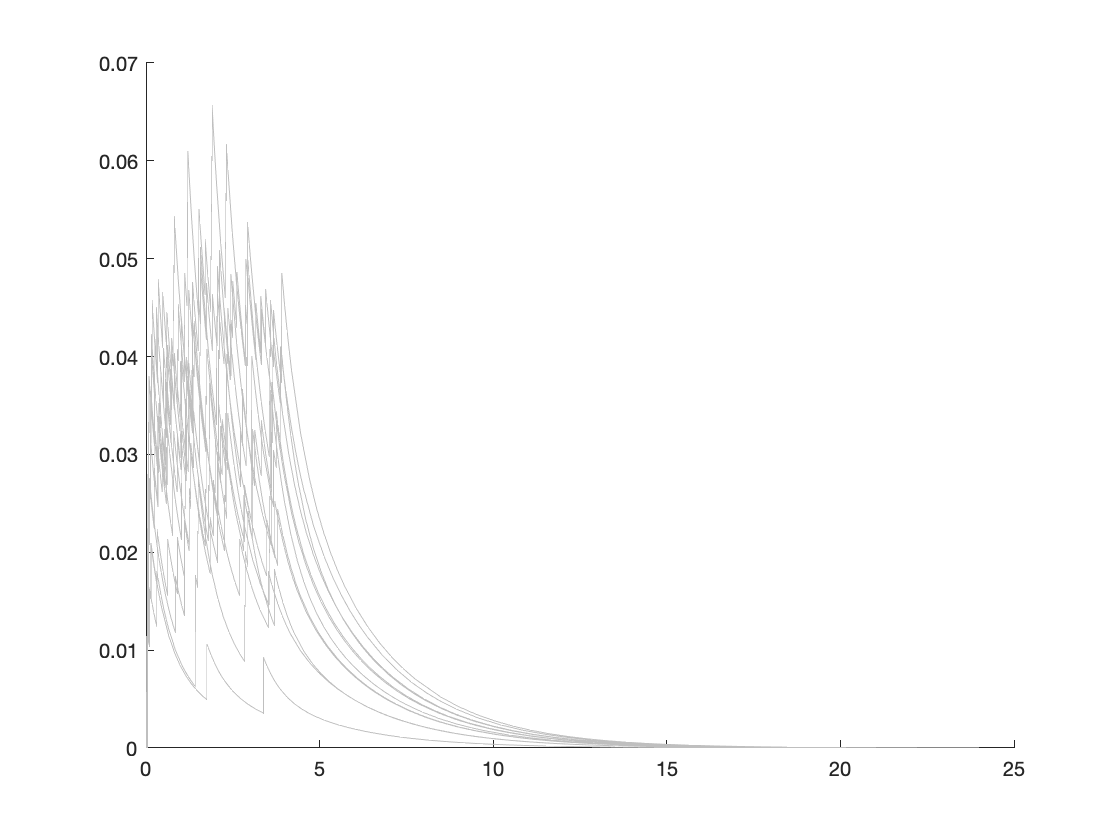

hold on

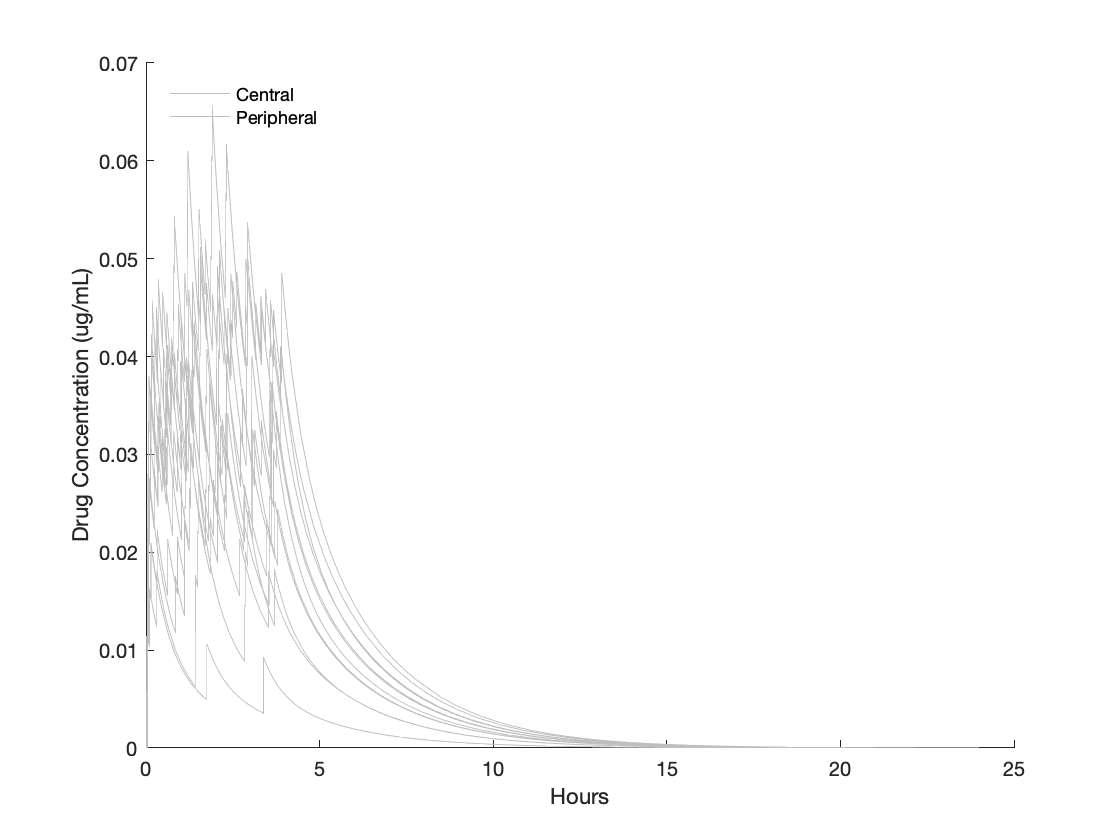


%plot all concentration profiles as slate gray so the mean response pops
plot(t,sd(:,1),"Color",[0.75,0.75,0.75]); 
hold off

%use trapezoid function to find area under the curve for each profile
%area(i).AUC = trapz(sd(:,1));
%removed this above in favor of integrating on the interpolated profiles
%further down, which allows a standardized vector length to be used where
%10000 data points equals 24 hours.

pkprofile(i).concentration = sd(:,1);
pkprofile(i).time = t;
end

l = legend(species,'Location','NorthWest');
set(l,'String',{'Central','Peripheral'}); % changes legend entries for simplification
legend boxoff; % removes box surrounding legend
xlabel('Hours');
ylabel('Drug Concentration (ug/mL)');

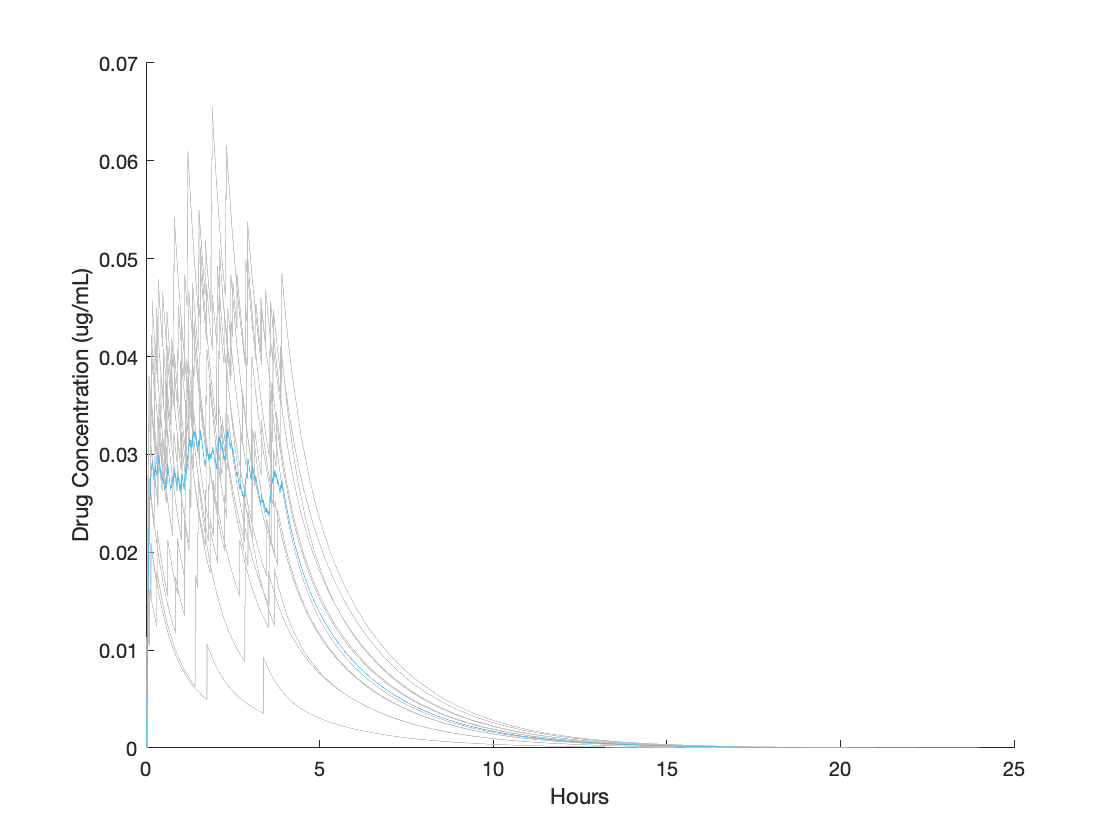

% go through each time and concentration vector for the simulations
figure
hold on
for p = 1:length(pkprofile)
    currentTime = pkprofile(p).time; %extract the time vector of the p-th simulation
    currentConcentration = pkprofile(p).concentration; %extract the concentration vector for the p-th simulation
    
    %the following adds a very small quantity to each time and
    %concentration value to make it unique, as the interpolation function
    %will fail if there are non-unique values in either vector (and there
    %will be)
    newTime = currentTime + linspace(0,0.00001,length(currentTime))'*1E-3;
    newConcentration = currentConcentration + linspace(0,0.00001,length(currentConcentration))'*1E-3;
    
    %create a new time vector from 0 to 24 hours with 10000 data points
    interpTime = linspace(0,24,10000)';
    
    %interpolate each concentration simulation to make it the same
    %dimension, for subsequent averaging
    interpConcentration = interp1(newTime,newConcentration,interpTime);
    
    %place the new interpolated time and concentration vector into the
    %pkprofile struct
    pkprofile(p).intertime = interpTime;
    pkprofile(p).interconcentration = interpConcentration;
    
    %calculate area under curve and use a different struct so it can be
    %written to an excel file more easily
    area(p).AUCtwo = trapz(interpConcentration(1:833)); %AUC for first 2 hours (first 833 data points)
    area(p).AUCfour = trapz(interpConcentration(1:1666));%AUC for first 4 hours 
    area(p).AUCtwentyfour = trapz(interpConcentration); %AUC for full 24 hours
    
    %find max concentration achieved for each curve
    [area(p).maxconcentration,area(p).indexofmax] = max(interpConcentration);
    
    %convert the index of the max concentration to a time in minutes
    %there are 10000 samples for 24 hours, which is ~7 samples per minute
    area(p).maxminutes = (area(p).indexofmax/7);
        
    %plot all individual profiles overlaid, and in gray
    plot(interpTime,interpConcentration,"Color",[0.75,0.75,0.75])
end

%make a zero array to hold all of the interpolated concentration profiles
conarray = zeros(10000,length(pkprofile));

%loop through pkprofile and extract each interpolated concentration profile
%and place it in a column of the conarray vector
for w = 1:length(pkprofile)
    conarray(:,w) = pkprofile(w).interconcentration;
end

%find the mean of all the interpolated concentration profiles
intermean = mean(conarray,2);

%plot the mean concentration profile on top of the original traces
plot(pkprofile(1).intertime,intermean)
xlabel('Hours');
ylabel('Drug Concentration (ug/mL)');
hold off

   FIG to SVG converter version 2020.01.0, maintained by Salva Ardid (https://github.com/kupiqu/fig2svg).


% export the graph to an SVG file 
fig2svg('pk.svg');

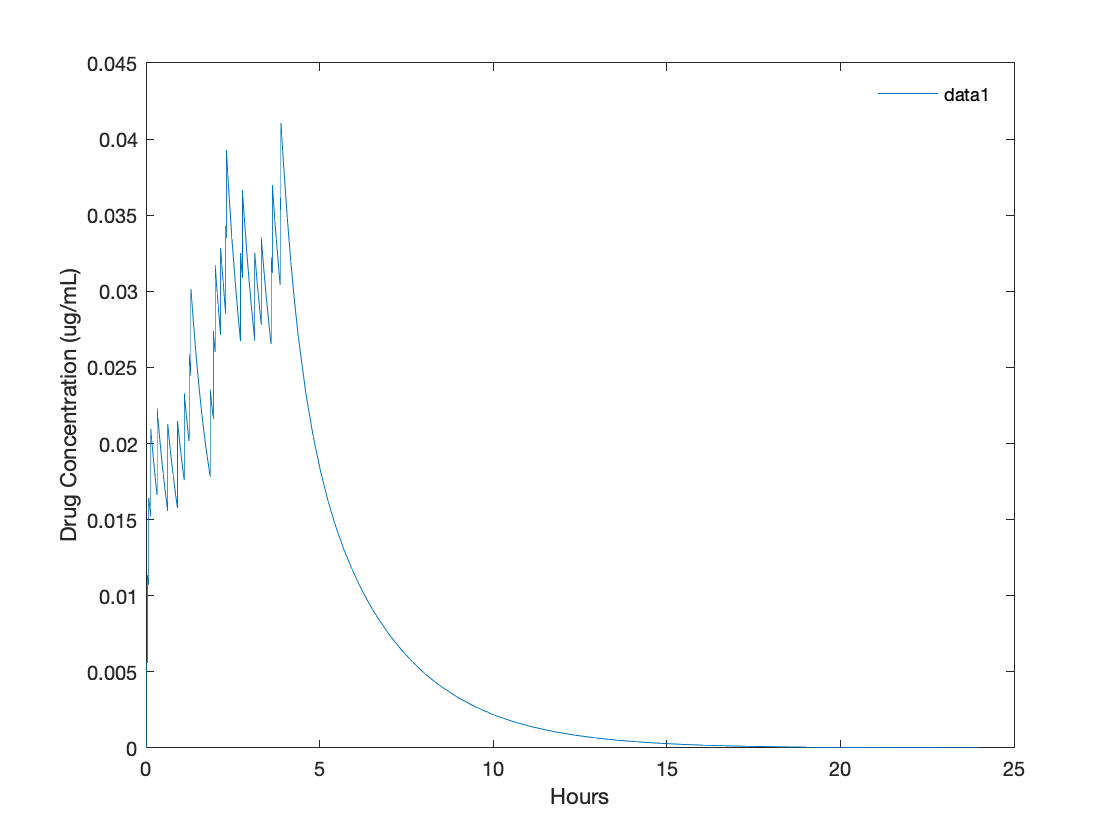


figure
plot(pkprofile(7).time,pkprofile(7).concentration)


legend boxoff; % removes box surrounding legend
xlabel('Hours');
ylabel('Drug Concentration (ug/mL)');

save area
T = struct2table(area,'AsArray',true);
filename = 'area.xlsx';
writetable(T,filename);


*Copyright 2015 The MathWorks, Inc.*